clear all
close all;
clc;

## Tf Generation


m1=1;
m2=1;
k1=(86+1)/15;
b2=k1;
k2=(1+86)/100;
b1=k2;
k3=k2/2;
A=[0 1 0 0;
    -(k1+k3)/m1 -b1/m1 k3/m1 0;
    0 0 0 1;
    k3/m2 0 -(k2+k3)/m2 -b2/m2];
B=[0 ;1/m1 ;0 ;0]; 
C=[1 0 1 0]; 
D=0;
[b,a]= ss2tf(A,B,C,D);
sys=tf(b,a);
fb = bandwidth(sys);
Ts=0.05*2*pi/fb; %seconds
sysd = c2d(sys, Ts,'zoh');
[c,d]=tfdata(sysd,'v');


## Estimation


N_samples=500;
t=0:Ts:Ts*N_samples;
tt=size(t,2);

u(1)=0;
u(2)=0;
u(3)=0;
u(4)=0;
for i=5:N_samples
    u(i)=sin((pi/12)*(i-4)*fb);
end

%%noise=[0,0,0,0,.01*randn(1,tt-5)];
%%u=noise-mean(noise)
%%u=u+noise;
%%u=noise
num=c

num =          0    0.0040   -0.0024   -0.0038    0.0023


den=d

den =     1.0000   -3.4552    4.4764   -2.5652    0.5445


dd=[d(1,2:5)]

dd =    -3.4552    4.4764   -2.5652    0.5445


init=[dd,c]

init =    -3.4552    4.4764   -2.5652    0.5445         0    0.0040   -0.0024   -0.0038    0.0023


% Sampling
y(1)=0;
y(2)=0;
y(3)=0;
y(4)=0;
%%thetainitial=
for temp=5:N_samples
    y(temp)=[-(y(temp-1:-1:temp-4)),(u(temp:-1:temp-4))]*(init');
end

phi=[];

phi(1,:)=[0 0 0 0 0 0 0 0]

phi =      0     0     0     0     0     0     0     0


phi(2,:)=[0 0 0 0 0 0 0 0]

phi =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


phi(3,:)=[0 0 0 0 0 0 0 0]

phi =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


phi(4,:)=[0 0 0 0 0 0 0 0]

phi =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


for temp=5:N_samples
    phi(temp,:)=[-(y(temp-1:-1:temp-4)),(u(temp-1:-1:temp-4))];
end

 Y=y(1:end)';
theta_hat=((phi'*phi)^-1)*phi'*Y;
normpara=norm(theta_hat-[den(2:end),num(2:end)]')

normpara = 1.3363e-05

normy=norm(Y-phi*theta_hat)

normy = 1.2560e-08

rmsd=sqrt(sum(((theta_hat-[den(2:end),num(2:end)]').^2)/8))

rmsd = 4.7247e-06

error=[normpara;rmsd;normy]

error = 	1.0e+-4 *

    0.1336
    0.0472
    0.0001


sysdd=tf([0,theta_hat(5:end)'],[1,theta_hat(1:4)'],Ts);
theta_hat

theta_hat =    -3.4552
    4.4764
   -2.5652
    0.5445
    0.0040
   -0.0024
   -0.0038
    0.0023


disp([den(2:end),num(2:end)]')

   -3.4552
    4.4764
   -2.5652
    0.5445
    0.0040
   -0.0024
   -0.0038
    0.0023



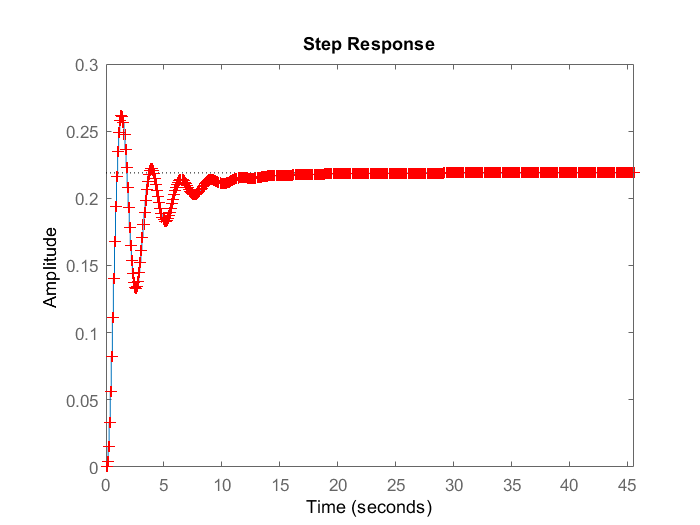

figure
step(sysdd,t)
hold on
step(sysd,t,'r+')

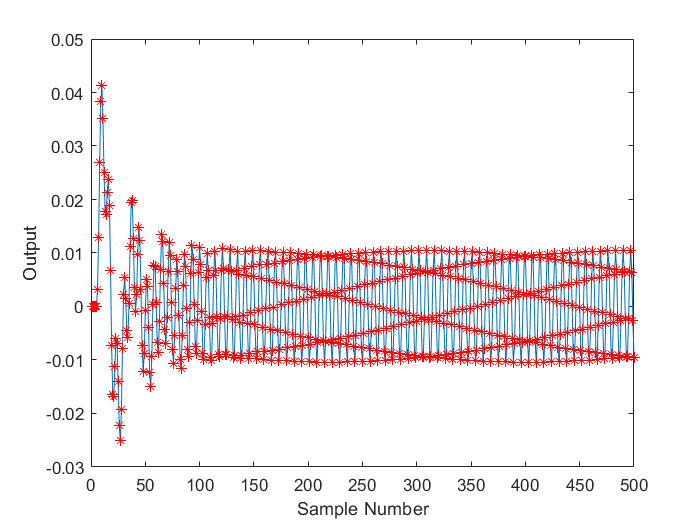

figure
plot(Y)
hold on
plot(phi*theta_hat,'r*')
xlabel('Sample Number')
ylabel('Output')